# Q2. Transfer Learning - Image Classification *(40 points)*

## 1. Pretrained network (3)

###     1.1. Import GoogLeNet (1)

net = imagePretrainedNetwork("googlenet")

net =   dlnetwork - 속성 있음:

         Layers: [143×1 nnet.cnn.layer.Layer]
    Connections: [169×2 table]
     Learnables: [116×3 table]
          State: [0×3 table]
     InputNames: {'data'}
    OutputNames: {'prob'}
    Initialized: 1

  요약 보기(summary 참조).


###     1.2. What is the input image size of GoogLeNet? (2)

      Enter your code to ouput the input image size of GoogLeNet.

layers = net.Layers

layers =   다음 계층을 포함한 143×1 Layer 배열:

     1   'data'                           영상 입력              224×224×3 영상 (정규화: 'zerocenter')
     2   'conv1-7x7_s2'                   2차원 컨벌루션          64개 7×7×3 컨벌루션(스트라이드: [2  2], 채우기: [3  3  3  3])
     3   'conv1-relu_7x7'                 ReLU                  ReLU
     4   'pool1-3x3_s2'                   2차원 최댓값 풀링       3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  1  0  1])
     5   'pool1-norm1'                    교차 채널 정규화        교차 채널 정규화 (요소당 채널 5개)
     6   'conv2-3x3_reduce'               2차원 컨벌루션          64개 1×1×64 컨벌루션(스트라이드: [1  1], 채우기: [0  0  0  0])
     7   'conv2-relu_3x3_reduce'          ReLU                  ReLU
     8   'conv2-3x3'                      2차원 컨벌루션          192개 3×3×64 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
     9   'conv2-relu_3x3'                 ReLU                  ReLU
    10   'conv2-norm2'                    교차 채널 정규화        교차 채널

layer1 = layers(1)

layer1 =   ImageInputLayer - 속성 있음:

                      Name: 'data'
                 InputSize: [224 224 3]
        SplitComplexInputs: 0

   하이퍼파라미터
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


## 2. Importing dataset (5)

###     2.1. Create an image datastore (3)

      Create an image datastore which references the folder of the dataset.

imageDS = imageDatastore("/Users/eukkcha/Desktop/Sejong/AI/week8_midterm/q2_data",...
    "IncludeSubfolders",true,"LabelSource","foldernames")

imageDS =   ImageDatastore - 속성 있음:

                       Files: {
                              ' .../e030b20928e90021d85a5854ee454296eb70e3c818b413449df6c87ca3ed_640.jpg';
                              ' .../e030b20929e90021d85a5854ee454296eb70e3c818b413449df6c87ca3ed_640.jpg';
                              ' .../e030b2092be90021d85a5854ee454296eb70e3c818b413449df6c87ca3ed_640.jpg'
                               ... and 1997 more
                              }
                     Folders: {
                              '/Users/eukkcha/Desktop/Sejong/AI/week8_midterm/q2_data'
                              }
                      Labels: [butterfly; butterfly; butterfly ... and 1997 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
              

###     2.2 What ouput classes does the dataset contain? (2)

      Enter your code to output the classes of the dataset.

classes = categories(imageDS.Labels)

classes = 10×1 cell 배열
    {'butterfly'}
    {'cat'      }
    {'chicken'  }
    {'cow'      }
    {'dog'      }
    {'elephant' }
    {'horse'    }
    {'sheep'    }
    {'spider'   }
    {'squirrel' }


*           View a sample image of each class*

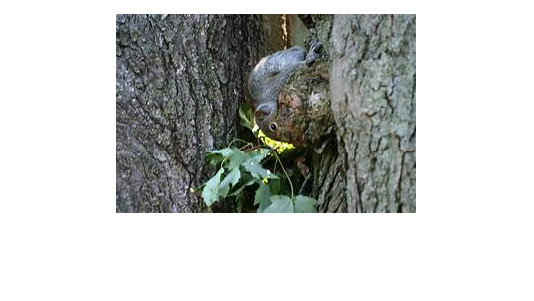

    %-------------- DO NOT modify this code--------------
    selectedClass="squirrel";
    classIdx = contains(imageDS.Files,selectedClass);
    countClass = sum(classIdx);
    randNum = randi([1,countClass],1);
    classRowNum = find(classIdx);
    classRandIm = readimage(imageDS, classRowNum(1)+randNum-1);
    imshow(classRandIm)

    %----------------------------------------------------

## 3. Preparing Data (5)

###     3.1. Split dataset (2)

      Split the dataset into train(0.8) and test data(0.2). 

- **For an optional argument, input "**`randomized`**" option.**

[trainImg,testImg] = splitEachLabel(imageDS,0.8,"randomized")

trainImg =   ImageDatastore - 속성 있음:

                       Files: {
                              ' .../e030b20928e90021d85a5854ee454296eb70e3c818b413449df6c87ca3ed_640.jpg';
                              ' .../e030b20929e90021d85a5854ee454296eb70e3c818b413449df6c87ca3ed_640.jpg';
                              ' .../e030b2092be90021d85a5854ee454296eb70e3c818b413449df6c87ca3ed_640.jpg'
                               ... and 1597 more
                              }
                     Folders: {
                              '/Users/eukkcha/Desktop/Sejong/AI/week8_midterm/q2_data'
                              }
                      Labels: [butterfly; butterfly; butterfly ... and 1597 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
             

testImg =   ImageDatastore - 속성 있음:

                       Files: {
                              ' .../e831b10b2ee90021d85a5854ee454296eb70e3c818b413449df6c87dafef_640.jpg';
                              ' ...e831b50f2df71c22d2524518b7444f92e37fe5d404b0144390f8c770a2e9b5_640.jpg';
                              ' ...32b10e2efc043ed1584d05fb1d4e9fe777ead218ac104497f5c97faee9bdba_640.jpg'
                               ... and 397 more
                              }
                     Folders: {
                              '/Users/eukkcha/Desktop/Sejong/AI/week8_midterm/q2_data'
                              }
                      Labels: [butterfly; butterfly; butterfly ... and 397 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
              

###     3.2. Augment data (3)

      Resize the dataset for transfer learning.

- **Resize the images to ****110 x 110****.**

- **For an optional input argument, input ****"**`gray2rgb`**" for "**`ColorPreprocessing`**"**** option.**

trainData = augmentedImageDatastore([110,110],trainImg,"ColorPreprocessing","gray2rgb")

trainData =   augmentedImageDatastore - 속성 있음:

             NumObservations: 1600
                       Files: {1600×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'gray2rgb'
                  OutputSize: [110 110]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


testData = augmentedImageDatastore([110,110],testImg,"ColorPreprocessing","gray2rgb")

testData =   augmentedImageDatastore - 속성 있음:

             NumObservations: 400
                       Files: {400×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'gray2rgb'
                  OutputSize: [110 110]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


## 4. Modifying Network (10)

Modify appropriate layers of GoogLeNet so that the network works for your dataset and then, export the network into your workspace. 

- **Note that the input image size should be ****110 x 110****.**

- **Be sure to ****name your network 'net_1' and include it into the zip file****, when you submit your answer.**

## 5. Training Network (7)

Create appropriate training options to obtain good prediction accuracy for the test data.

###     5.1. Create training options (5)

      The training options you **SHOULD KEEP** are as follows. The rest of training options are tunerable.

- Max Epochs: 10

- Display training progress and accuracy for the training data

opts = trainingOptions("sgdm","MaxEpochs",10,"InitialLearnRate",0.001,...
    "Plots","training-progress","Metrics","accuracy","ExecutionEnvironment","auto","Shuffle","once")

opts =   TrainingOptionsSGDM - 속성 있음:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-03
                       MaxEpochs: 10
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 128
                         Shuffle: 'once'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
             ObjectiveMetricName: 'loss'
                  CheckpointPath: '

###     5.2. Train Network (2)

      Train network.

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    TrainingAccuracy
    _________    _____    ___________    _________    ____________    ________________
            1        1       00:00:02        0.001          7.6894              7.8125
훈련이 중지됨: 수동으로 중지됨


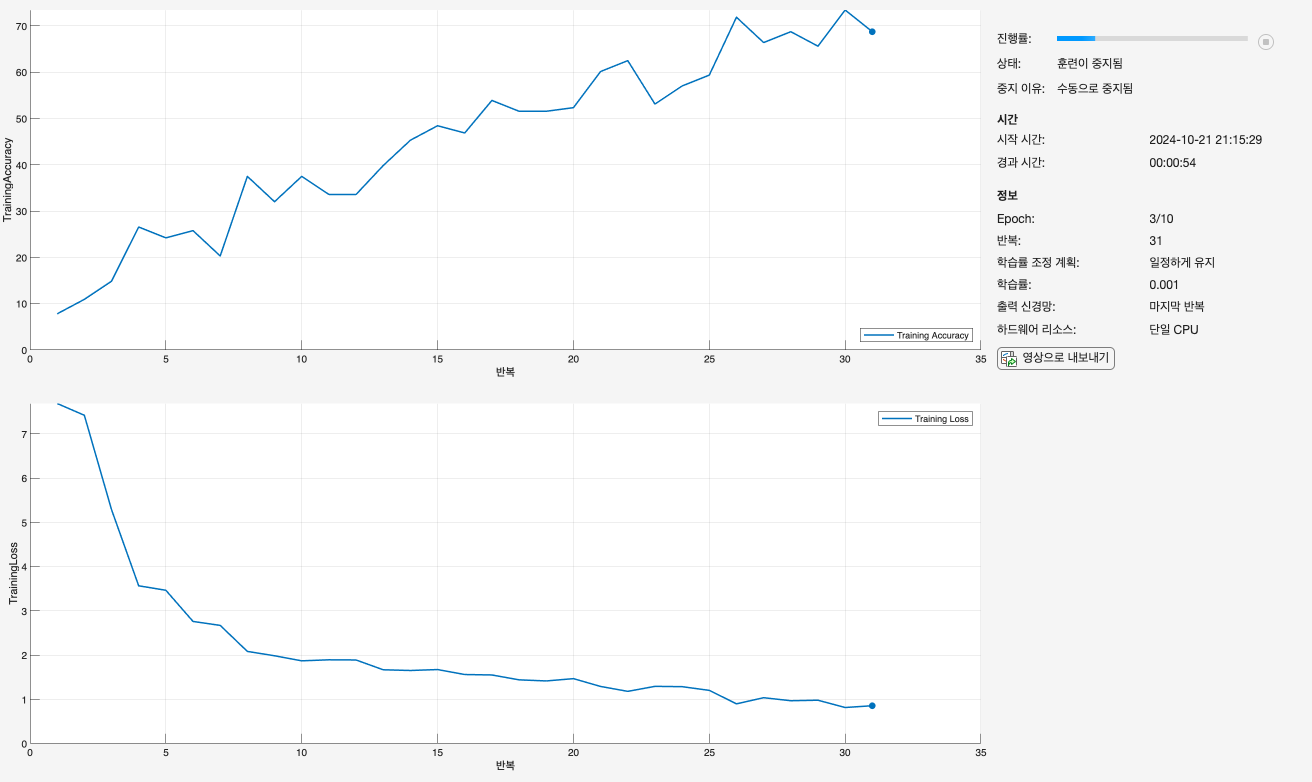

landnet =   dlnetwork - 속성 있음:

         Layers: [143×1 nnet.cnn.layer.Layer]
    Connections: [169×2 table]
     Learnables: [116×3 table]
          State: [0×3 table]
     InputNames: {'data'}
    OutputNames: {'prob'}
    Initialized: 1

  요약 보기(summary 참조).


landnet = trainnet(trainData,net_1,"crossentropy",opts)

## 6. Evaluating network (10)

Evaluate the network by classifying the test data, calculating the classification accuracy and displaying a confusion chart.

###     6.1. Predict the class of the test data (4)

scores = minibatchpredict(landnet,testData)

scores = 400×10 single 행렬
    0.9256    0.0022    0.0087    0.0020    0.0031    0.0025    0.0009    0.0024    0.0378    0.0147
    0.7743    0.0034    0.0080    0.0059    0.0041    0.0038    0.0023    0.0092    0.1599    0.0290
    0.7558    0.0073    0.0208    0.0183    0.0240    0.0098    0.0091    0.0197    0.1188    0.0163
    0.3319    0.0409    0.0409    0.0230    0.1128    0.0619    0.0436    0.0139    0.1855    0.1456
    0.7499    0.0030    0.0192    0.0057    0.0032    0.0050    0.0078    0.0066    0.1461    0.0535
    0.7509    0.0152    0.0268    0.0124    0.0089    0.0141    0.0086    0.0145    0.0987    0.0498
    0.2068    0.1102    0.1558    0.0834    0.0718    0.0226    0.0825    0.0362    0.1720    0.0587
    0.2710    0.0424    0.0132    0.0673    0.0358    0.0343    0.3256    0.0583    0.1348    0.0172
    0.6224    0.0115    0.0141    0.0034    0.0129    0.0073    0.0025    0.0096    0.3070    0.0094
    0.7983    0.0053    0.0125    0.0252    0.0146    0.0046    0

[testPred,score] = scores2label(scores,classes)

testPred = 400×1 categorical 배열
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     horse 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     spider 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     spider 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     chicken 
     butterfly 
     butterfly 


score = 400×1 single 열 벡터
    0.9256
    0.7743
    0.7558
    0.3319
    0.7499
    0.7509
    0.2068
    0.3256
    0.6224
    0.7983


###     6.2. Calculate the prediction accuracy (4)

testGT = testImg.Labels

testGT = 400×1 categorical 배열
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 


testAcc = nnz(testGT == testPred) / numel(testPred)

testAcc = 0.7275

###     6.3. Display a confusion chart (2)

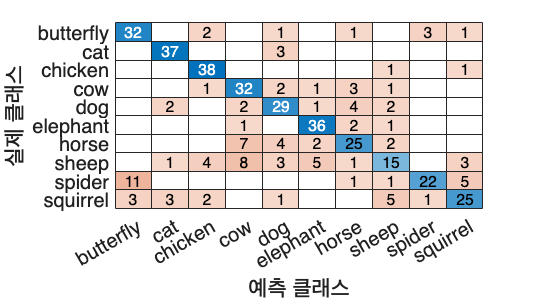

confusionchart(testGT,testPred)